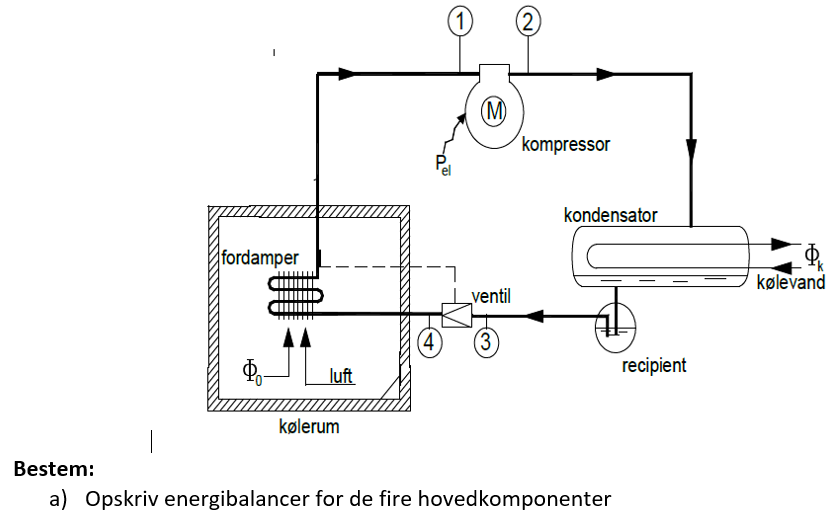

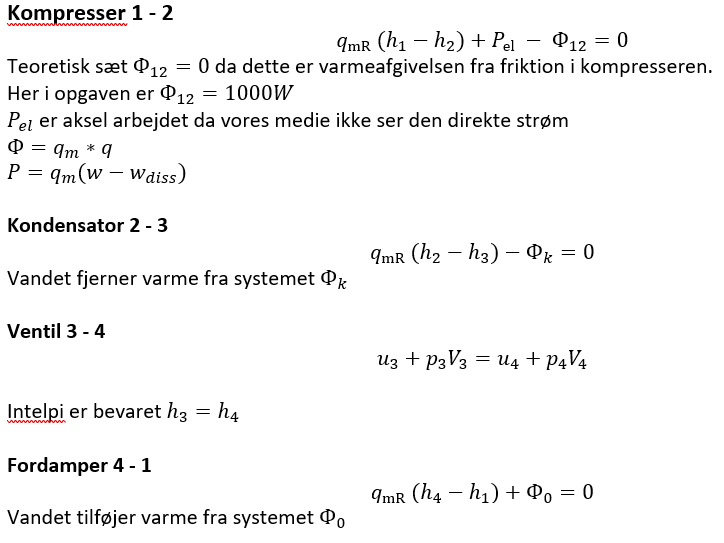

### b)

Indtegn processen i log *p*,*h*-diagrammet for kølemidlet R134a.

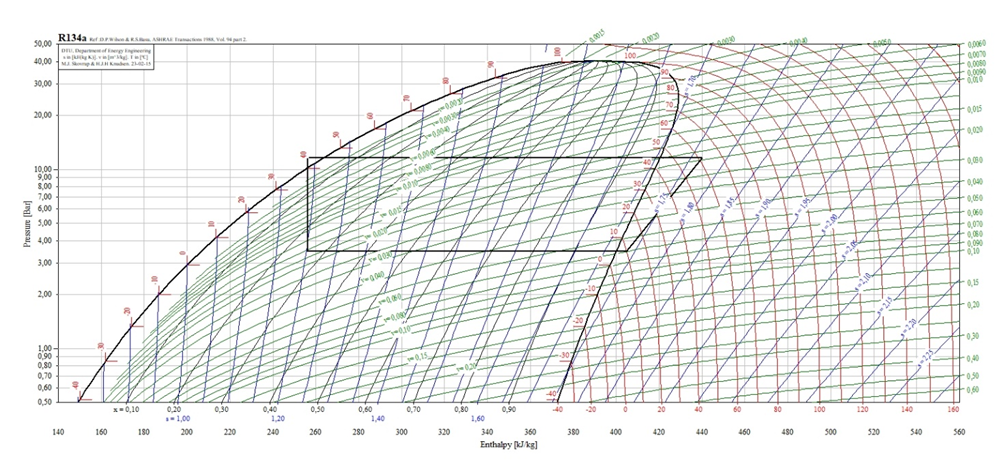

### c)

Cirkuleret kølemiddelmassestrøm i anlægget.

Phi_0 = 20 *1e3; %W
h_4 = 256.160 *1e3; % aflæst i coolpack % [J/kg] 
h_1 = 404.785 *1e3; % aflæst i coolpack % [J/kg] 

syms q_mR_sym
q_mR = solve(q_mR_sym * (h_4 - h_1) + Phi_0, q_mR_sym);
q_mR_ = vpa(q_mR,7)

$$q\_mR\_ = 0.1345669$$

kølemiddelmassestrømmen er således 0,109 $kg\ s^{-1}$

### d)

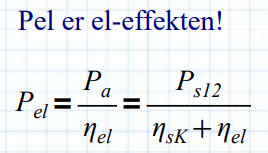

Kompressorens tilførte akseleffekt samt kondensatorydelsen.

syms P_el_sym
Phi_tab = 1000; % W %varmestrømmen fra kompresseren %  
h_2_sub = 440.135 *1e3; % aflæst i coolpack % [J/kg] 
eta_sK = 0.72;
eta_el = 1.00;
P_el = q_mR * (h_2_sub - h_1) / (eta_sK * eta_el);
P_el_ = vpa(P_el, 6)

$$P\_el\_ = 6606.86$$

h_2 = (P_el - Phi_tab)/q_mR + h_1;

syms Phi_K_sym  
h_3 = h_4; % aflæst i coolpack % [J/kg] 
Phi_K = solve(q_mR * (h_2 - h_3) - Phi_K_sym, Phi_K_sym);
Phi_K_ = vpa(Phi_K,7)

$$Phi\_K\_ = 25606.86$$

Således har vi akseleffekt($P_{el}$) unden friktion på 6607 W og en kondensatorydelsen på 25607 W

### e)

Køleanlæggets effektfaktor (COP)

eta_kol = Phi_0/P_el;
eta_kol_ = vpa(eta_kol,5) 

$$eta\_kol\_ = 3.0272$$